## Calculating The Stress-Energy Tensor For a Metric

%% Alcubierre
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.9;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

### Compute Energy Tensor

The stress-energy-momentum tensor can be calculated simply by calling getEnergyTensor(Metric)

% Compute energy tensor
EnergyTensor = getEnergyTensor(Metric);

### Basic Plotting

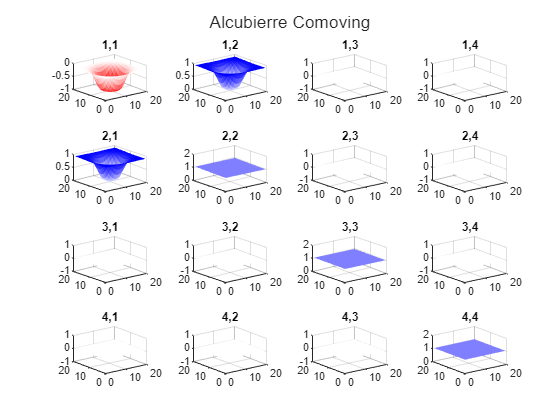

% Plotting Metric
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        colormap(h,redblue(Metric.tensor{i,j}(1,:,:,round(worldCenter(4)))))
    end
end
sgtitle(Metric.name)

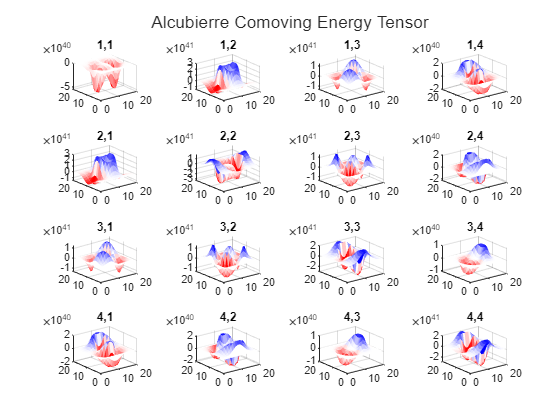


% Plotting Energy Tensor
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(EnergyTensor.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name + " Energy Tensor")

## Calculating the Eulerian Stress-Energy Tensor

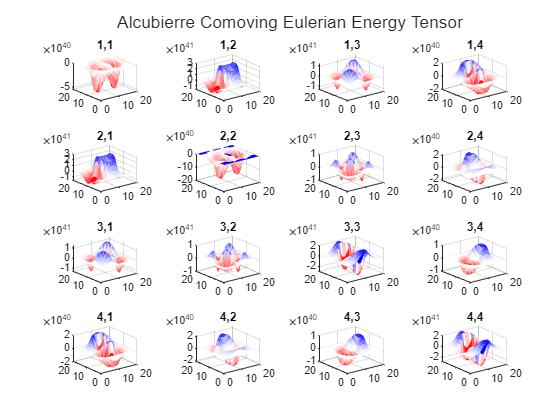

% Convert to Eulerian Frame
EnergyTensorEulerian = doFrameTransfer(Metric,EnergyTensor,"Eulerian");

% Plotting Eulerian Energy Tensor
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(EnergyTensorEulerian.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name + " Eulerian Energy Tensor")